clear;close all;
%-----------------------------------
%初始化
%nPoint：采样点数
%z0：设定的距离
%sigma：波数
%色散相位：-4*pi*((b0+z0)+b1*sigma).*sigma;
%-----------------------------------
nPoint = 2^18;
L = 5;
z0 = 10;
b0 = 35;
b1 = -10;
sigma = 0:(L/1024):(nPoint-1)*(L/1024);
% sigma = 0:0.0038*1024/1024:(nPoint-1)*0.0038*1024/1024;
%加窗 window1
window1 = ones(1,1024);
fSigma = fitfSigma(sigma);
fSigma = sigmult(fSigma,1:2^18,window1,1:2^10);
pSigma=-4*pi*((b0+z0)+b1*sigma).*sigma;
pSigma = sigmult(pSigma,1:2^18,window1,1:2^10);
iSigma = fSigma.*exp(1i*pSigma);
disp("光谱")

光谱


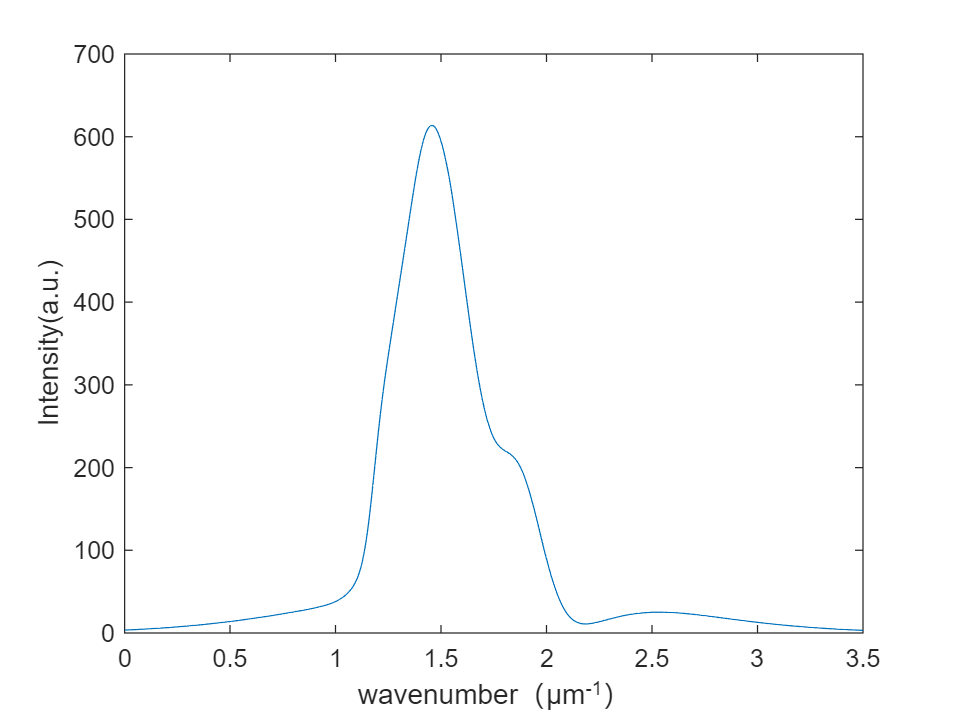

plot(sigma(1:2^10),fSigma(1:2^10));
xlim([0 3.5]);
xlabel('wavenumber（\mum^{-1}）')
ylabel('Intensity(a.u.)')

disp("有色散噪声的相位")

有色散噪声的相位


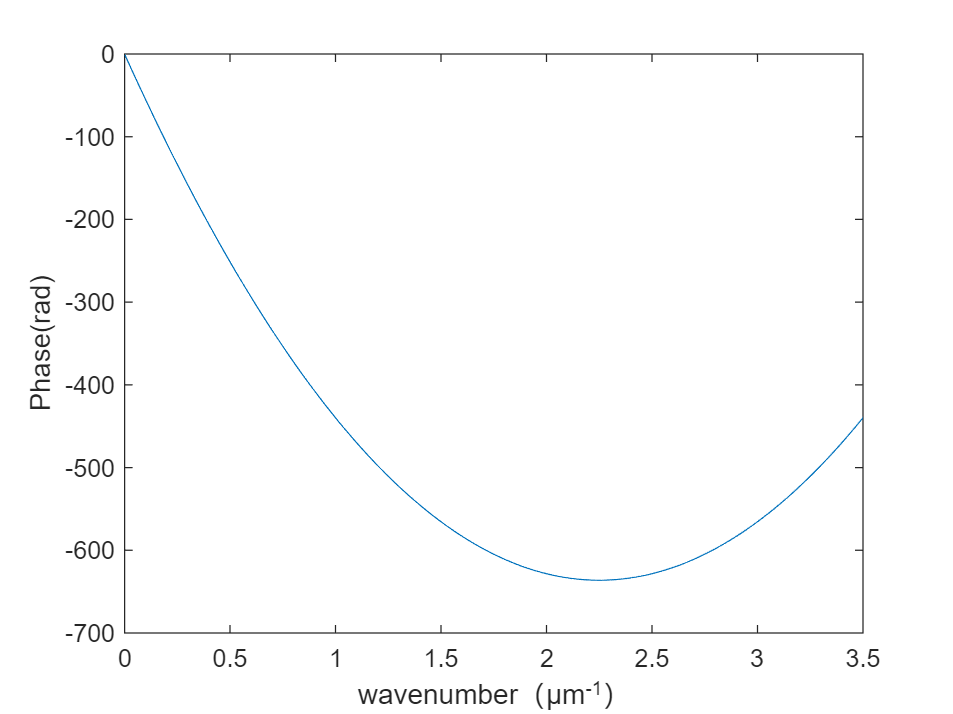

plot(sigma,pSigma);
xlim([0 3.5]);
xlabel('wavenumber（\mum^{-1}）')
ylabel('Phase(rad)')

%-----------------------------------
%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
powerTotal = 0;
for n=1:1:nPoint
    powerTotal=powerTotal+fSigma(n);
end
p = 0;
for n=1:1:nPoint
    p = p+ fSigma(n)*sigma(n);
end
lambdaA = powerTotal/p;

shiftnumber1 = round((1/lambdaA)/(L/1024));
fSigma = circshift(fSigma,-shiftnumber1);

% intensityhalf = fSigma(1:nPoint/2);
% fSigma(1:nPoint/2)=fSigma(nPoint/2+1:nPoint);
% fSigma(nPoint/2+1:nPoint) = intensityhalf;
% plot(sigma-sigma(end)/2,fSigma);
% xlim([-1.5 1.5]);
% xlabel('Wavenumber(\mum^{-1})')
% ylabel('Intensity(a.u.)')

[minP, indexP] = min(pSigma);
shiftnumber2 = round(sigma(indexP)/(L/1024));
pSigma = circshift(pSigma,-shiftnumber2);

% intensityhalf = pSigma(1:nPoint/2);
% pSigma(1:nPoint/2)=pSigma(nPoint/2+1:nPoint);
% pSigma(nPoint/2+1:nPoint) = intensityhalf;
% plot(sigma-sigma(end)/2,pSigma);
% xlim([-1.5 1.5]);
% xlabel('Wavenumber(\mum^{-1})')
% ylabel('Phase(rad)')
% plot(sigma,pSigma);

iSigma = fSigma.*exp(1i*pSigma);
deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase = (angle(ifftIsigma));
%找到振幅最大值
[max1,index]= max(intensity);
zData(index)

ans = 1.8703

phase(index)

ans = -1.9758

disp("未作最小二乘的FFT后的振幅分布")

未作最小二乘的FFT后的振幅分布


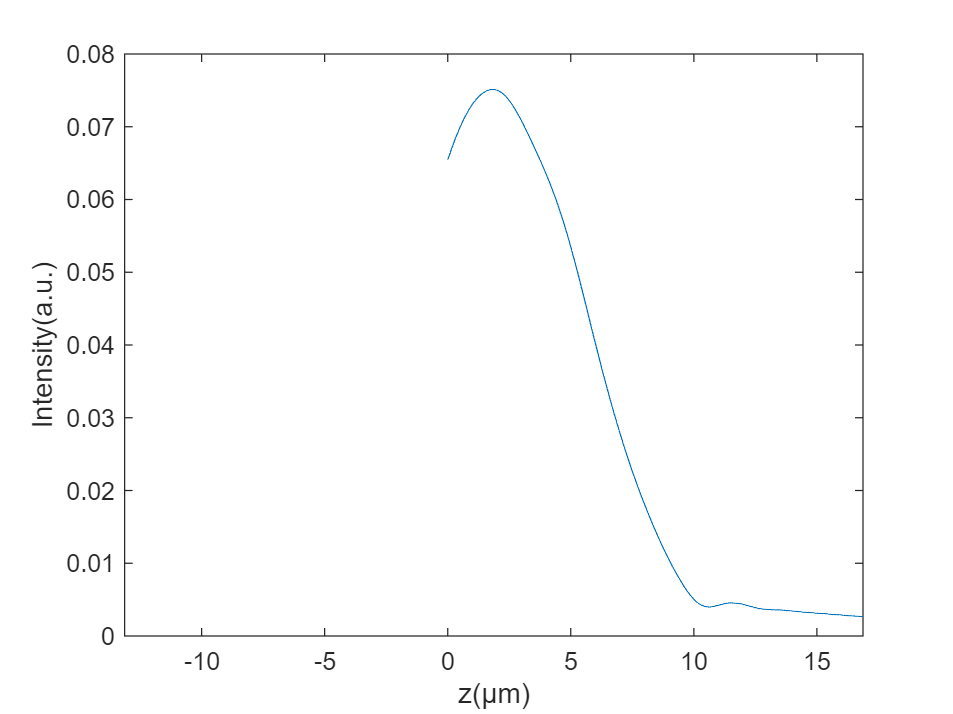

plot(zData,intensity);
xlim([zData(index)-15 zData(index)+15]);
xlabel('z(\mum)')
ylabel('Intensity(a.u.)')

disp("未作最小二乘的FFT后的相位分布")

未作最小二乘的FFT后的相位分布


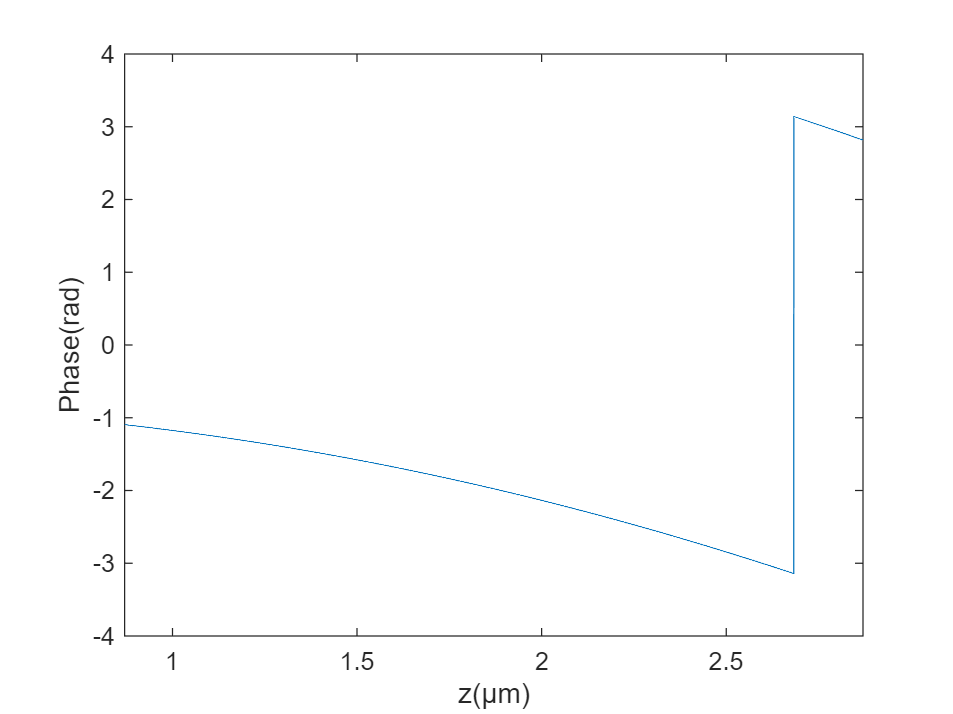

plot(zData,phase);
xlim([zData(index)-1 zData(index)+1]);
xlabel('z(\mum)')
ylabel('Phase(rad)')

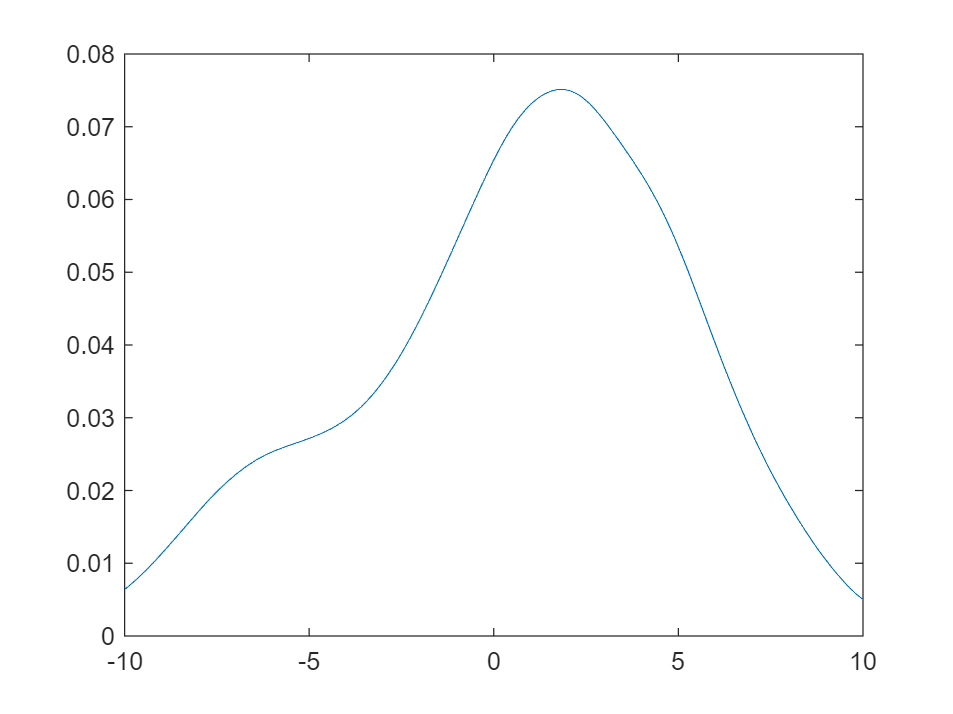


intensityhalf = intensity(1:nPoint/2);
intensity(1:nPoint/2)=intensity(nPoint/2+1:nPoint);
intensity(nPoint/2+1:nPoint) = intensityhalf;
phasehalf = phase(1:nPoint/2);
phase(1:nPoint/2)=phase(nPoint/2+1:nPoint);
phase(nPoint/2+1:nPoint) = phasehalf;

intensity111 = intensity;

zData = zData-zData(end)/2;
plot(zData,intensity111);
xlim([-10 10])

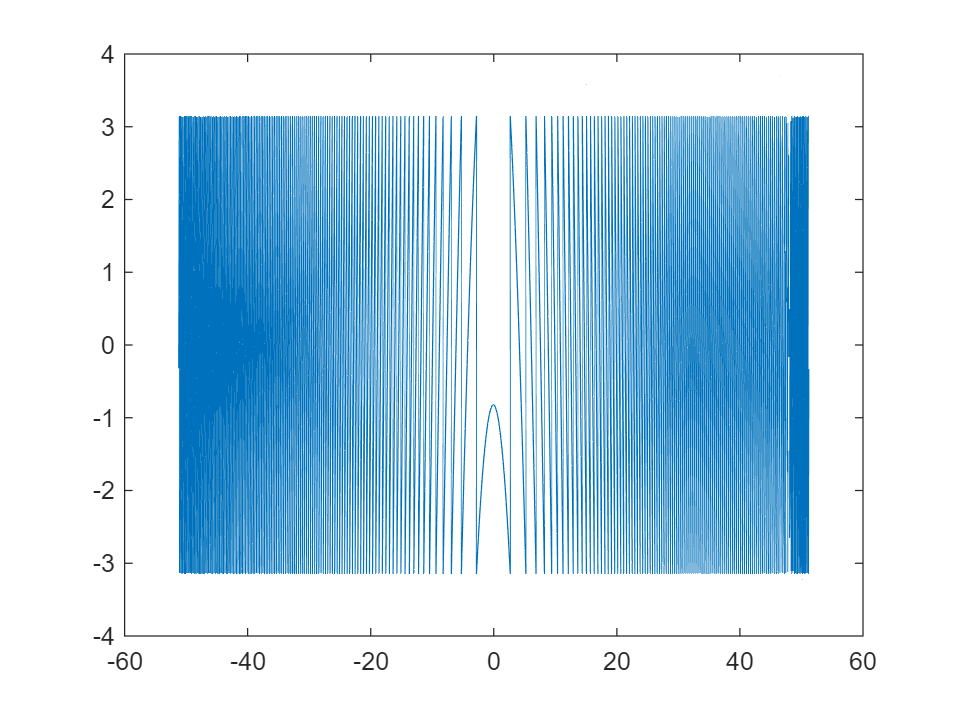

plot(zData,phase);

[maxI, indexI] = max(intensity);
za1 = zData(indexI)

za1 = 1.8703

phase(indexI)

ans = -1.9758

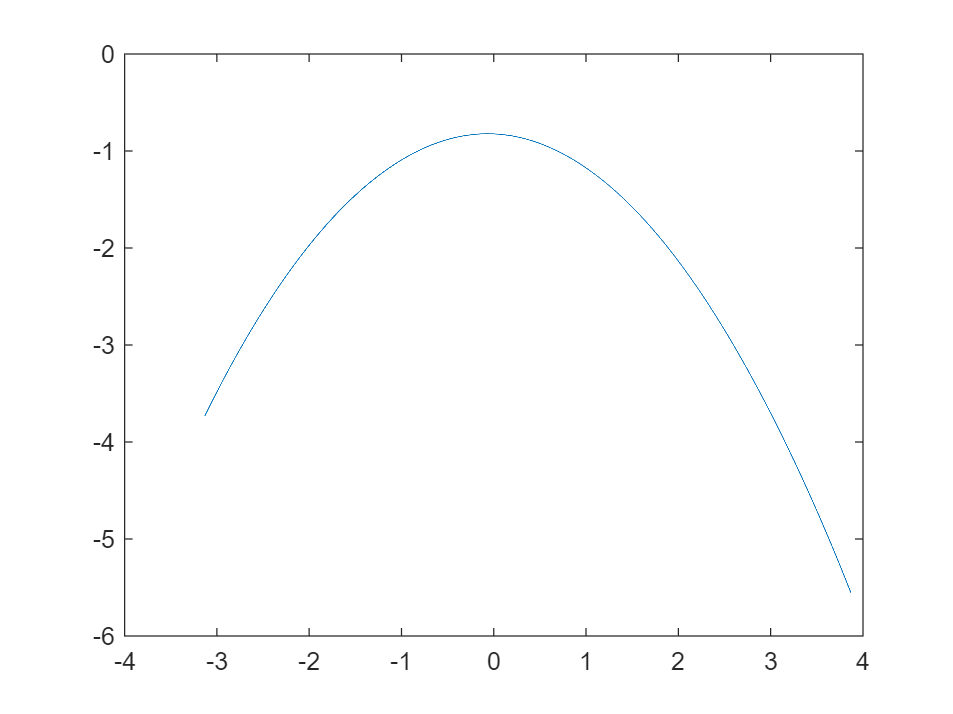

%-----------------------------------
%仿真计算振幅最大及相位零值
%za1：振幅最大值
%zp1：相位零值
%-----------------------------------
unwrapZend = zData(abs(zData-(za1+2))<0.001);
unwrapZ_1 = zData(abs(zData-(za1-5))<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = indexI;
unwrapNe = find(zData==unwrapZend(end));
unwrapN_1 = find(zData==unwrapZ_1(1));
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(indexI);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));%+4*pi*(1/lambdaA).*zData(unwrapN_1:unwrapNe)

unwrapPha1 = unwrapPha(unwrapN_1:unwrapNe);
%-----------------------------------
%初始化
%nPoint：采样点数
%z0：设定的距离
%sigma：波数
%色散相位：-4*pi*((b0+z0)+b1*sigma).*sigma;
%-----------------------------------
nPoint = 2^18;
z0 = 10;
b0 = 35;
b1 = -10;
sigma = 0:(L/1024):(nPoint-1)*(L/1024);
% sigma = 0:0.0038*1024/1024:(nPoint-1)*0.0038*1024/1024;
%加窗 window1
window1 = ones(1,1024);
fSigma = fitfSigma(sigma);
fSigma = sigmult(fSigma,1:2^18,window1,1:2^10);
pSigma=-4*pi*((b0+z0)+b1*(sigma)).*(sigma);
pSigma = sigmult(pSigma,1:2^18,window1,1:2^10);
pSigma = circshift(pSigma,-shiftnumber2);
shiftnumber3 = round((1/lambdaA)/(L/1024));
pSigma = circshift(pSigma,shiftnumber3);
iSigma = fSigma.*exp(1i*pSigma);
disp("光谱")

光谱


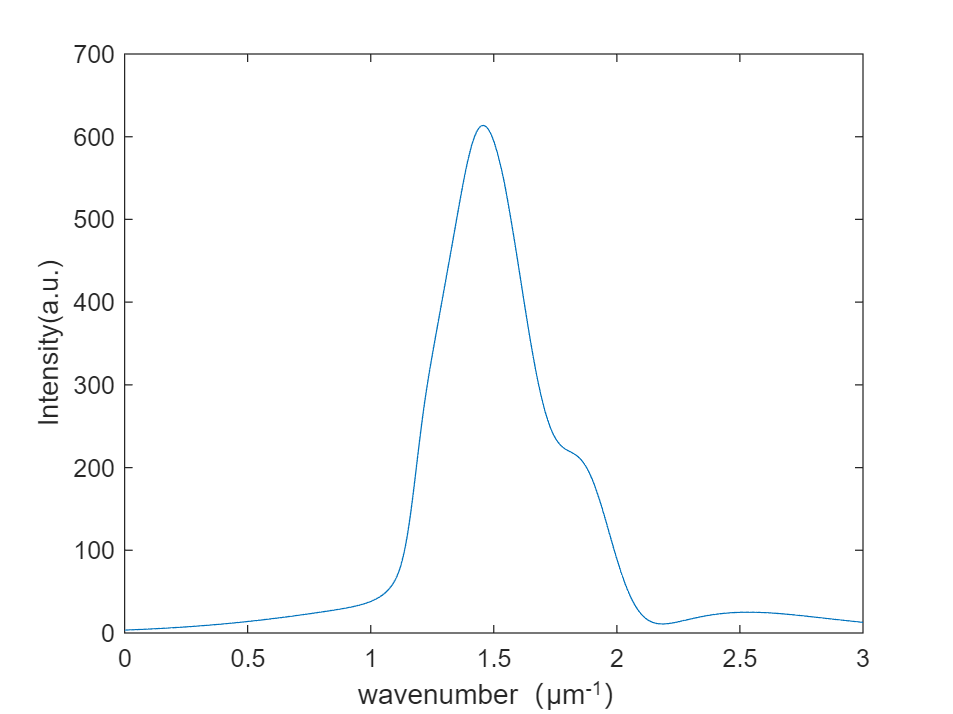

plot(sigma(1:2^10),fSigma(1:2^10));
xlim([0 3]);
xlabel('wavenumber（\mum^{-1}）')
ylabel('Intensity(a.u.)')

disp("有色散噪声的相位")

有色散噪声的相位


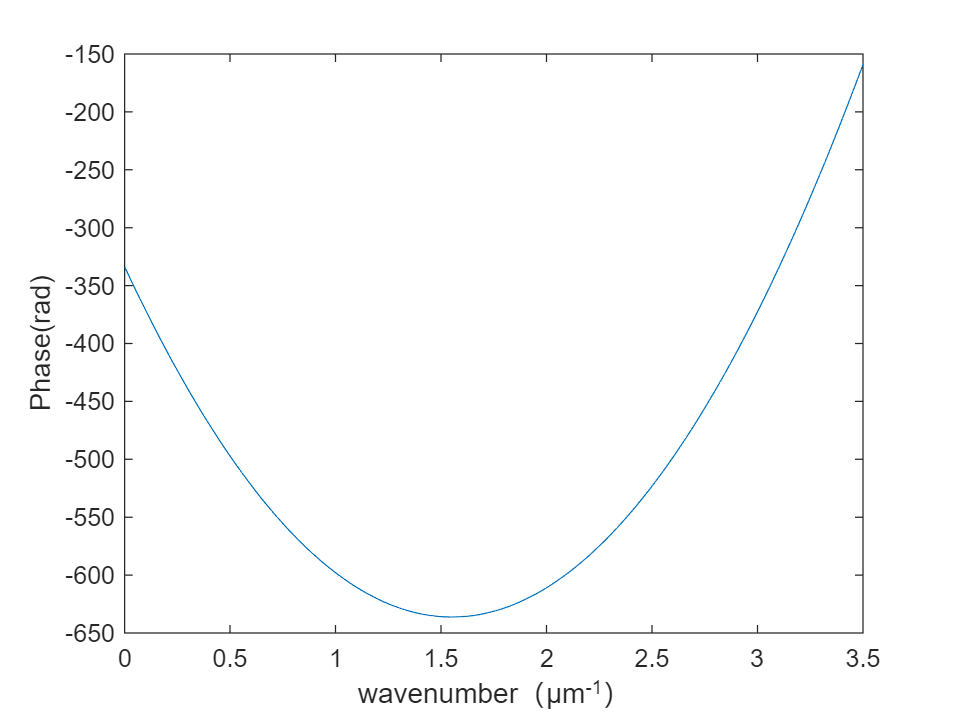


% intensityhalf = pSigma(1:nPoint/2);
% pSigma(1:nPoint/2)=pSigma(nPoint/2+1:nPoint);
% pSigma(nPoint/2+1:nPoint) = intensityhalf;
% plot(sigma-sigma(end)/2,pSigma);
% xlim([0 3]);
% xlabel('Wavenumber(\mum^{-1})')
% ylabel('Phase(rad)')
% plot(sigma,pSigma);


plot(sigma,pSigma);
xlim([0 3.5]);
xlabel('wavenumber（\mum^{-1}）')
ylabel('Phase(rad)')




deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity1 = abs(ifftIsigma);
phase = (angle(ifftIsigma));
[max2,index2]= max(intensity1);
disp("作最小二乘的FFT后的振幅分布")

作最小二乘的FFT后的振幅分布


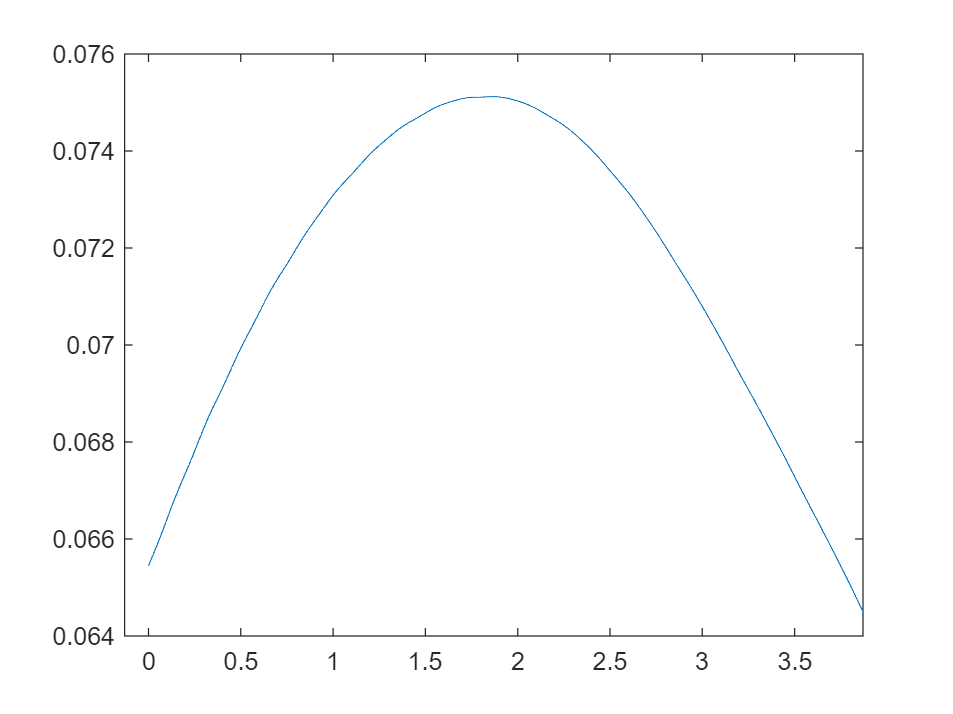

plot(zData,intensity1);
xlim([zData(index2)-2 zData(index2)+2]);

disp("作最小二乘的FFT后的相位分布")

作最小二乘的FFT后的相位分布


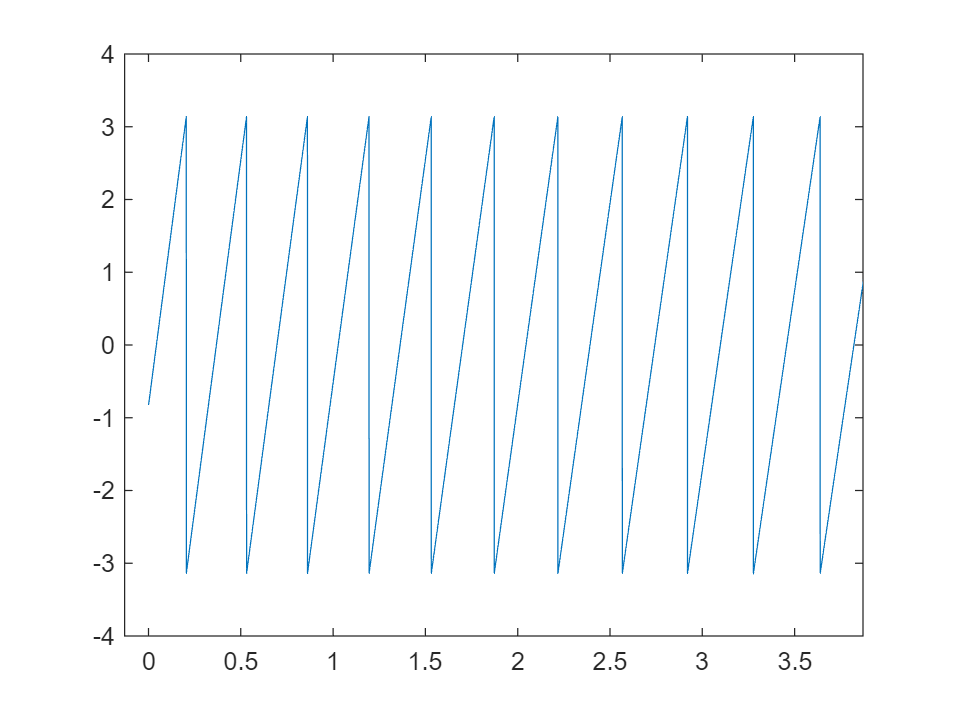

plot(zData,phase);
xlim([zData(index2)-2 zData(index2)+2]);

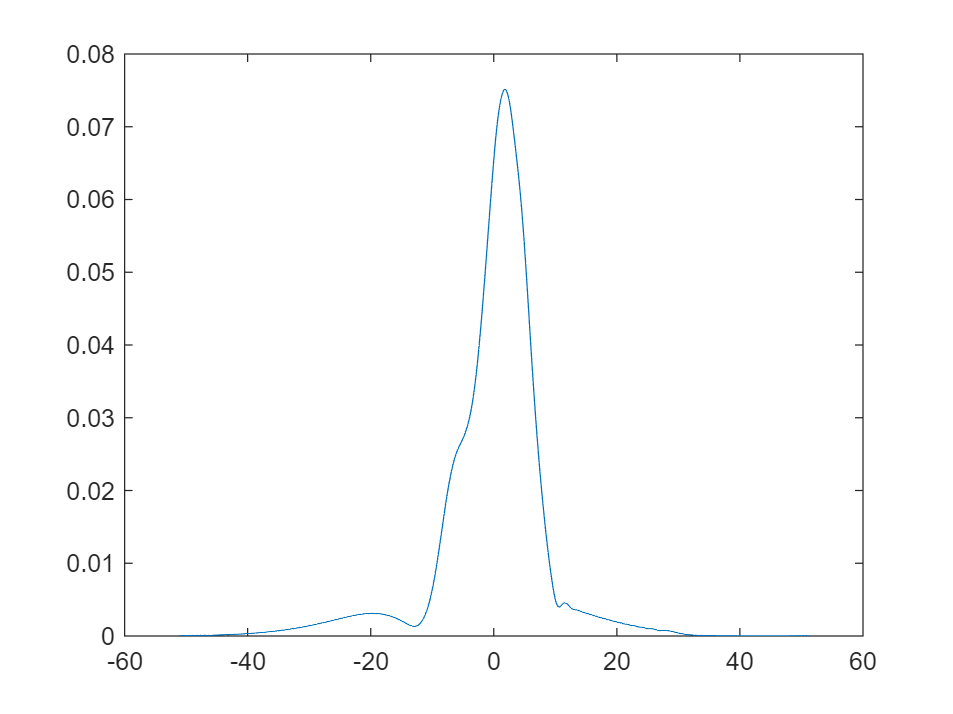


intensityhalf = intensity1(1:nPoint/2);
intensity1(1:nPoint/2)=intensity1(nPoint/2+1:nPoint);
intensity1(nPoint/2+1:nPoint) = intensityhalf;
phasehalf = phase(1:nPoint/2);
phase(1:nPoint/2)=phase(nPoint/2+1:nPoint);
phase(nPoint/2+1:nPoint) = phasehalf;
intensity112=intensity1;

zData = zData-zData(end)/2;
plot(zData,intensity1);

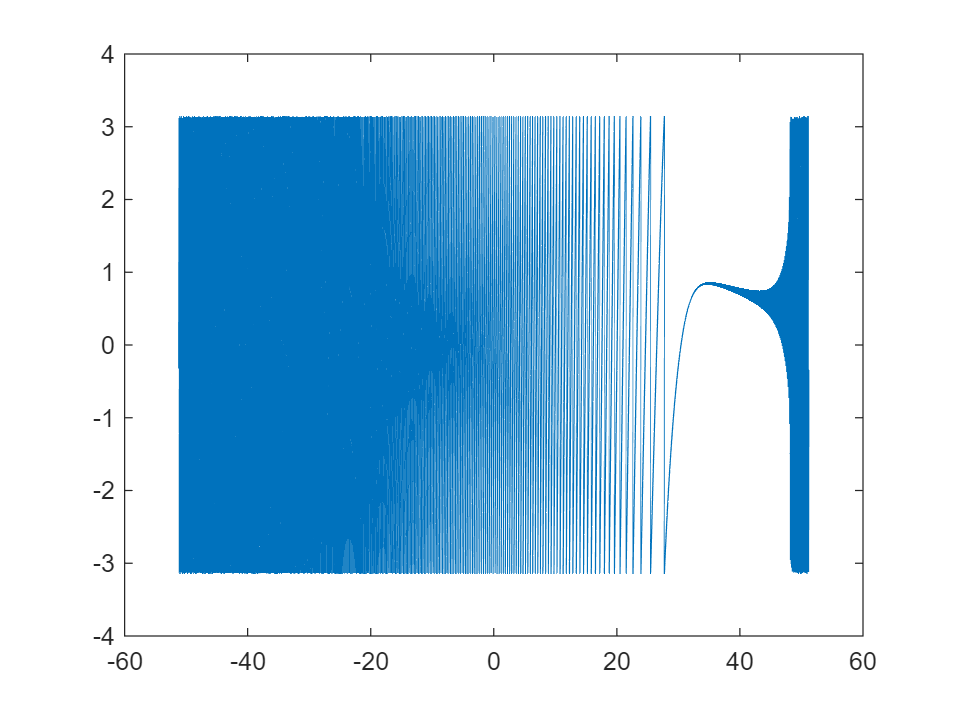

plot(zData,phase);

[maxI, index12] = max(intensity1);
za1 = zData(index12)

za1 = 1.8703

index12 = find(abs(zData-0)<0.0001)

index12 = 131072

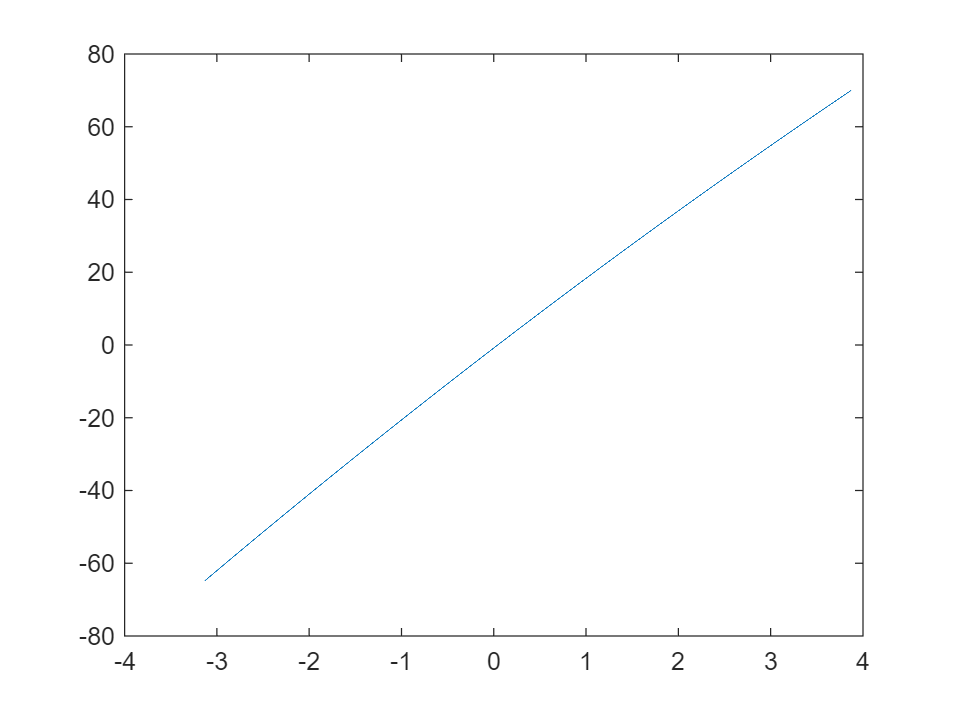

%-----------------------------------
%仿真计算振幅最大及相位零值
%za1：振幅最大值
%zp1：相位零值
%-----------------------------------
unwrapZend = zData(abs(zData-(za1+2))<0.001);
unwrapZ_1 = zData(abs(zData-(za1-5))<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = index12;
unwrapNe = find(zData==unwrapZend(end));
unwrapN_1 = find(zData==unwrapZ_1(1));
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index12);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

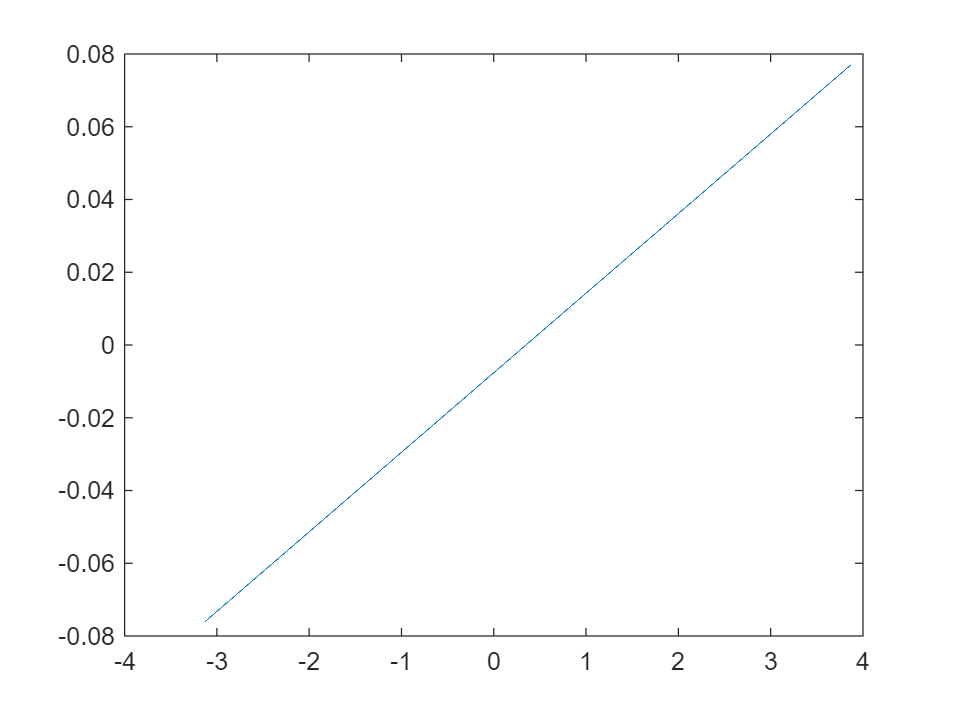

unwrapPha2 = unwrapPha(unwrapN_1:unwrapNe)-4*pi*(1/lambdaA)*zData(unwrapN_1:unwrapNe);
bijiao = unwrapPha2-unwrapPha1;
bijiao1 = (intensity112-intensity111);
plot(zData(unwrapN_1:unwrapNe),bijiao);

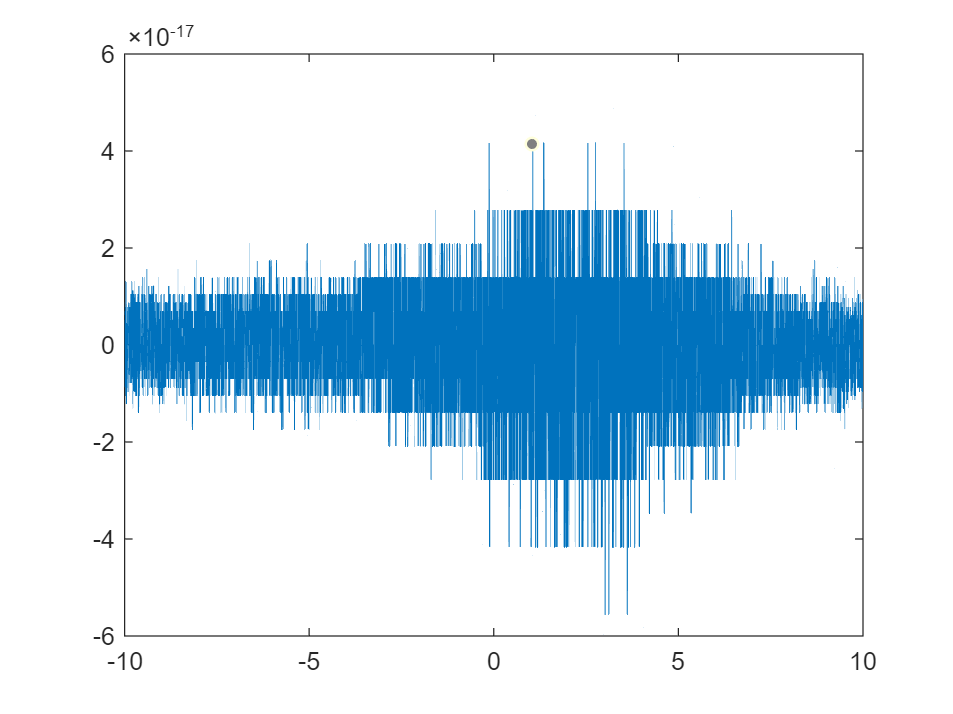

plot(zData,bijiao1);
xlim([-10 10])

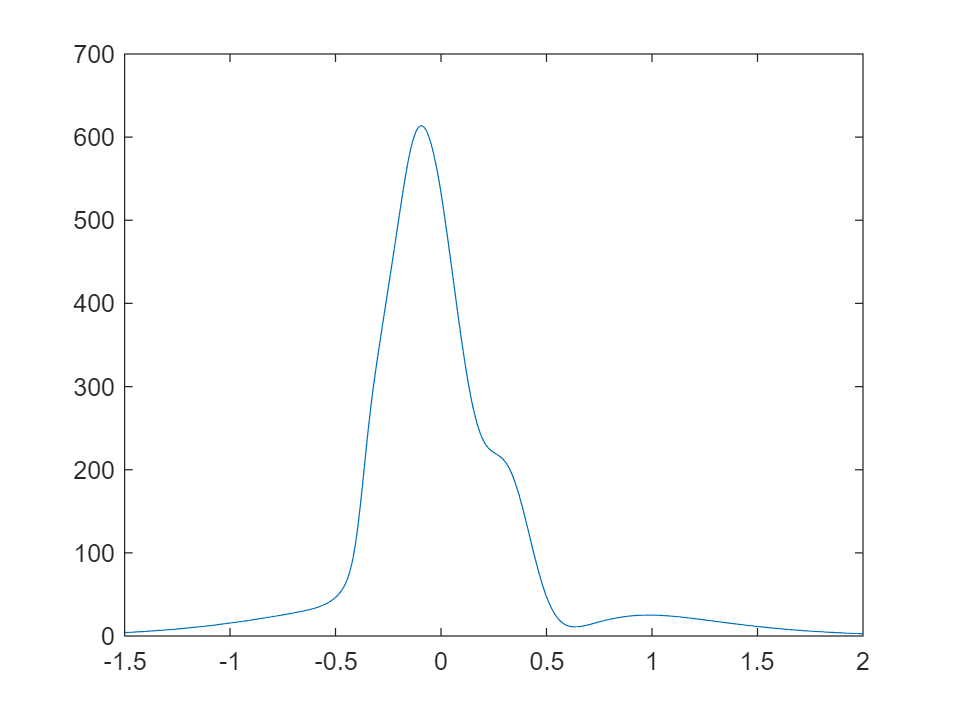


nPoint = 2^18;
z0 = 10;
b0 = 35;
b1 = -10;
sigma = 0:(L/1024):(nPoint-1)*(L/1024);
% sigma = 0:0.0038*1024/1024:(nPoint-1)*0.0038*1024/1024;
%加窗 window1
window1 = ones(1,1024);
fSigma = fitfSigma(sigma);
fSigma = sigmult(fSigma,1:2^18,window1,1:2^10);
shiftnumber1 = round((1/lambdaA)/(L/1024));
fSigma = circshift(fSigma,-shiftnumber1);

intensityhalf = fSigma(1:nPoint/2);
fSigma(1:nPoint/2)=fSigma(nPoint/2+1:nPoint);
fSigma(nPoint/2+1:nPoint) = intensityhalf;

plot(sigma-sigma(end)/2,fSigma);
xlim([-1.5 2]);


deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(fSigma);
intensity1 = abs(ifftIsigma);
phase = (angle(ifftIsigma));
[max2,index2]= max(intensity1);
disp("作最小二乘的FFT后的振幅分布")

作最小二乘的FFT后的振幅分布


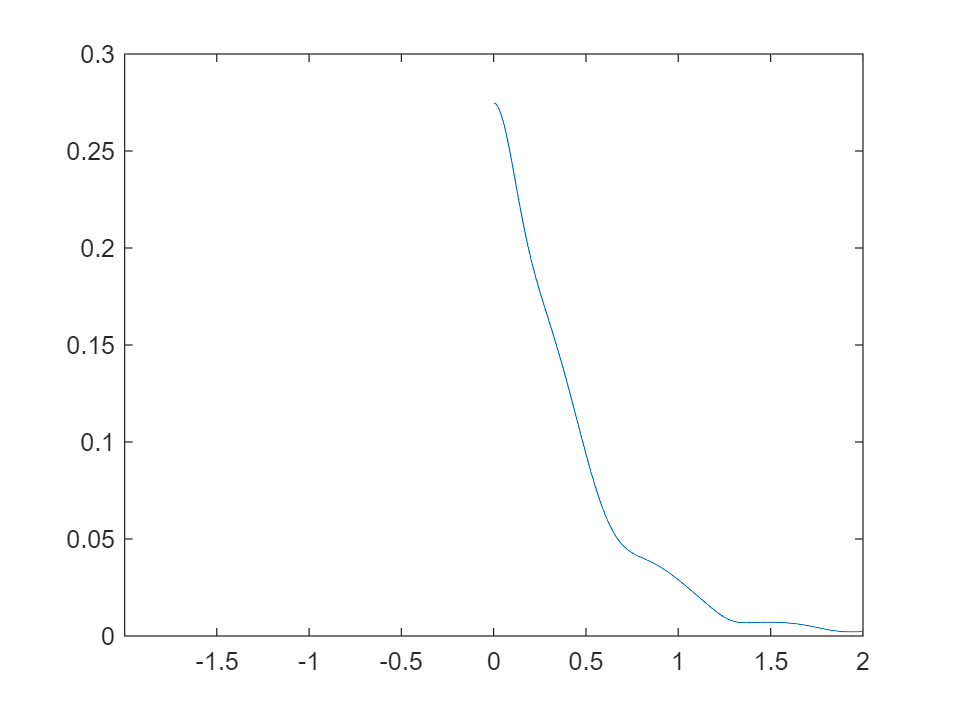

plot(zData,intensity1);
xlim([zData(index2)-2 zData(index2)+2]);

disp("作最小二乘的FFT后的相位分布")

作最小二乘的FFT后的相位分布


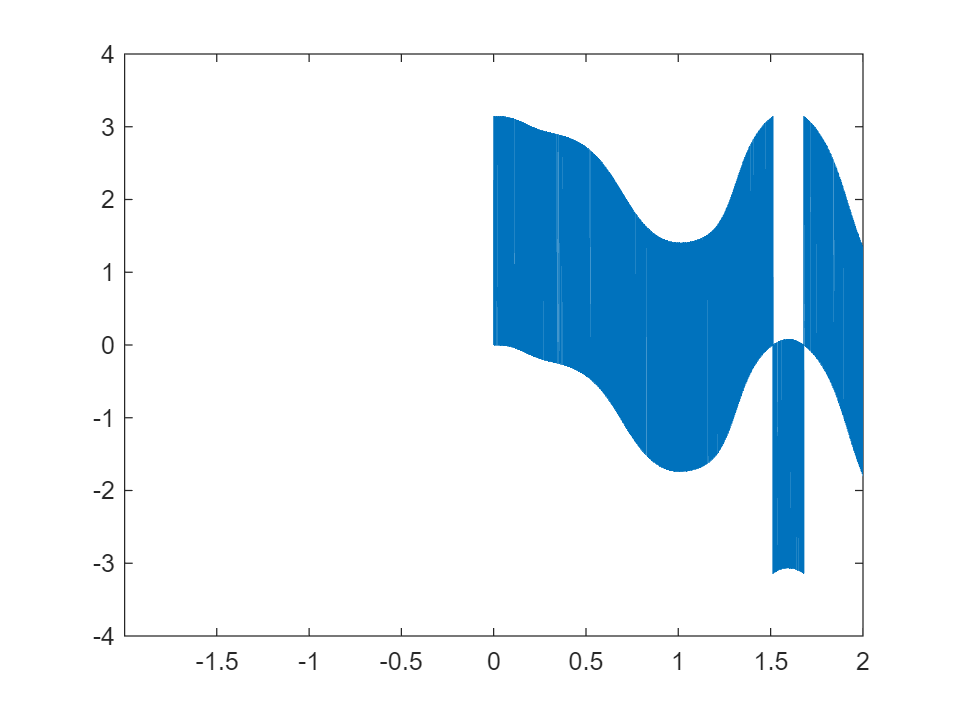

plot(zData,phase);
xlim([zData(index2)-2 zData(index2)+2]);

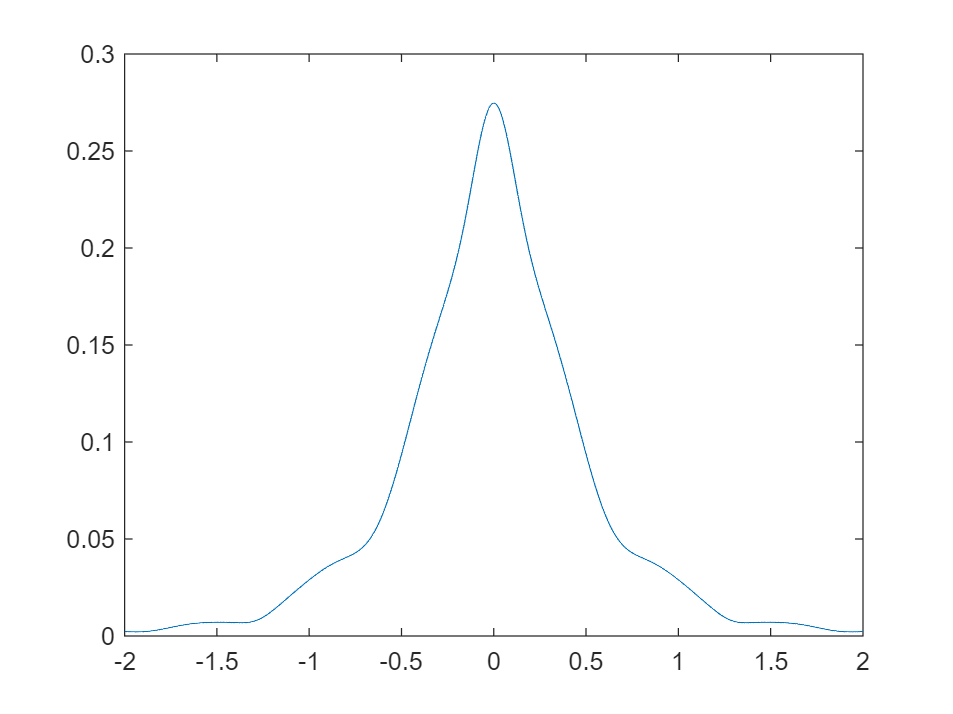


intensityhalf = intensity1(1:nPoint/2);
intensity1(1:nPoint/2)=intensity1(nPoint/2+1:nPoint);
intensity1(nPoint/2+1:nPoint) = intensityhalf;
phasehalf = phase(1:nPoint/2);
phase(1:nPoint/2)=phase(nPoint/2+1:nPoint);
phase(nPoint/2+1:nPoint) = phasehalf;

zData = zData-zData(end)/2;
plot(zData,intensity1);
xlim([-2 2])

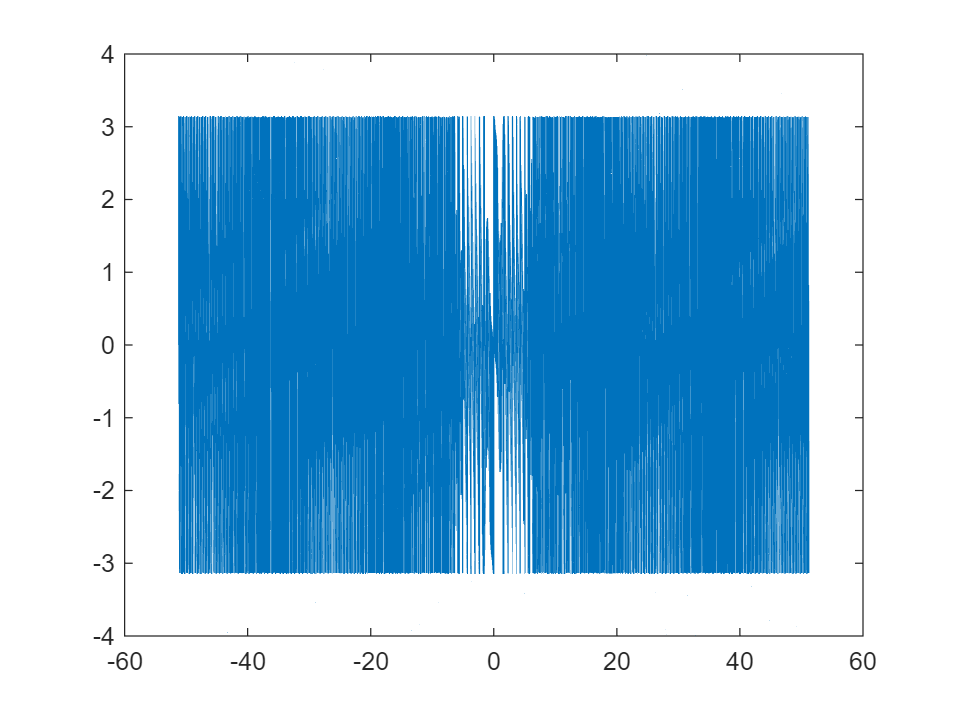

plot(zData,phase);

function fSigma = fitfSigma(x)
%Coefficients (with 95% confidence bounds):
       a1 =       88.19  ;%(51.68, 124.7)
       b1 =       1.378  ;%(1.347, 1.409)
       c1 =      0.1243  ;%(0.0879, 0.1606)
       a2 =      0.9322  ;%(-1.209, 3.073)
       b2 =       1.542  ;%(1.518, 1.565)
       c2 =     0.01341  ;%(-0.02512, 0.05195)
       a3 =       69.18  ;%(-6.223, 144.6)
       b3 =        1.27  ;%(1.228, 1.312)
       c3 =     0.07202  ;%(0.03205, 0.112)
       a4 =       528.7  ;%(493.5, 563.8)
       b4 =       1.488  ;%(1.483, 1.494)
       c4 =      0.2199  ;%(0.2153, 0.2245)
       a5 =       62.39  ;%(-14.96, 139.7)
       b5 =       1.207  ;%(1.188, 1.225)
       c5 =     0.05735  ;%(0.04772, 0.06698)
       a6 =         181  ;%(163.3, 198.6)
       b6 =        1.87  ;%(1.867, 1.873)
       c6 =       0.158  ;%(0.153, 0.1629)
       a7 =      -60.41  ;%(-80.21, -40.6)
       b7 =        1.92  ;%(1.789, 2.051)
       c7 =      0.4102  ;%(0.3363, 0.4841)
       a8 =       57.07  ;%(54.59, 59.55)
       b8 =       1.735  ;%(1.728, 1.742)
       c8 =       1.039  ;%(1.023, 1.054)
     fSigma = a1*exp(-((x-b1)/c1).^2) + a2*exp(-((x-b2)/c2).^2) +... 
              a3*exp(-((x-b3)/c3).^2) + a4*exp(-((x-b4)/c4).^2) + ...
              a5*exp(-((x-b5)/c5).^2) + a6*exp(-((x-b6)/c6).^2) + ...
              a7*exp(-((x-b7)/c7).^2) + a8*exp(-((x-b8)/c8).^2);
end
function [y,n] = sigmult(x1,n1,x2,n2)
%implements y(n) = x1(n) * x2(n);
%-----------------------------------
%[y,n]=siggadd(x1,n1,x2,n2)
%x1=first sequence over n1
%x2=first sequence over n1
%
n = min(min(n1),min(n2)):max(max(n1),max(n2));
y1 = zeros(1,length(n));
y2 = y1;
y1(find((n>=min(n1))&(n<=max(n1))==1))=x1;
y2(find((n>=min(n2))&(n<=max(n2))==1))=x2;
y=y1.*y2;
end
